# Mohammadreza Arani

## Convex Optimization

## 810100511

% Project 5:
clear;
clc;
close all;

% Load Data:
load('A:\Uni_Arshad\Term 2\Convex\Mine\Project\5\Hossein\mixture_coeffs_data.mat');

In this project we are about to :

*Estimating mixture coefcients. *

We are given *N *IID samples *x*1*, . . . , x**N **∈ ***R***m *from a distribution with mixture density.

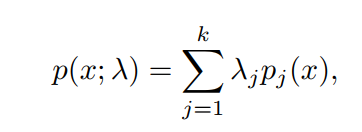

we have to estimate PDF, using a mixture model [meanning using different pdf and scalarization].

p1,..,pk are given! estimation parameters will be Lambdas!

% Lambdas are obtained using Maximum Lokelihood!
% Assuming i.i.d distributions ==>
% 

$p\left(x_1 ,\ldotp \ldotp \ldotp ,x_N \;,\;\lambda \right)=\prod_{i=1}^N p\left(x_i \;,\;\lambda \right)=\prod_{i=1}^N \sum_{j=1}^k \lambda_{j*\;} p_j \left(x_i \right)$ ==>

Using a Log() function ==> which is monotone and does not change the result in maximization gives:

                                                                            
$$\sum_{i=1}^N \log \left(\sum_{j=1}^k \lambda_j p_j \left(x_i \right)\right)$$


which will be an affine function with respect to Lambda and can be represented as a summation of Lambdas;

[ As we know, most PDFs are log concave ]   

    ==> logarithm of an affine function will be log concave due to the fact that any affine function is convex and concave at the same time!

    we choose its concavity to use maximum likelihood to be in the form of DCP rules!

The constraints are given as:

        
$$\begin{array}{l}
\;\;\;\;\;\;\;\;1^T \lambda =1\\
\;\;\;\;\;\;\;\;\;\lambda \ge 0
\end{array}$$


p  = densities

p =     0.0533         0    0.0107
    0.0409    0.3333    0.1031
    0.1735    0.3333    0.0448
    0.0779    0.3333    0.0785
    0.0293    0.3333    0.1162
    0.1934         0    0.0372
    0.1450    0.3333    0.0536
    0.0415    0.3333    0.1026
    0.0113         0    0.1556
    0.1256    0.3333    0.0598


## Part [b]:

% Using CVX_Matlab:
L2 = size(densities,2);
L1 = size(densities,1);
cvx_begin

    variables Lambdas(L2);

    Cost_func = 0;

    for i = 1 : L1
        Cost_func = Cost_func + log(p(i,:)*Lambdas);
    end

    maximize( Cost_func ); % the objective
    % and the constraints:
    subject to
        Lambdas >= 0;
        ones(1,L2)*Lambdas == 1; % Summation coeeficents of PDFs
        
cvx_end

 
Successive approximation method to be employed.
   For improved efficiency, SDPT3 is solving the dual problem.
   SDPT3 will be called several times to refine the solution.
   Original size: 304 variables, 103 equality constraints
   100 exponentials add 800 variables, 500 equality constraints
-----------------------------------------------------------------
 Cones  |             Errors              |
Mov/Act | Centering  Exp cone   Poly cone | Status
--------+---------------------------------+---------
100/100 | 8.000e+00  4.548e+00  2.187e-10 | Solved
100/100 | 2.152e+00  3.041e-01  0.000e+00 | Solved
100/100 | 1.046e-01  7.037e-04  0.000e+00 | Solved
100/100 | 1.679e-02  1.774e-05  1.611e-10 | Solved
100/100 | 2.234e-03  3.139e-07  5.515e-11 | Solved
  0/100 | 3.012e-04  5.479e-09  0.000e+00 | Solved
-----------------------------------------------------------------
Status: Solved
Optimal value (cvx_optval): -206.882
 


 The data fles mixture coeﬀs data.* contain code that generates *N *= 100 samples from a

mixture of  *k *= 3 distributions on **R**,

*                                                                    N *(3*, *4)*, **U*(*-*1*, *2)*, **L*(*-*2*, *3)*,*

with mixture coefcients.                                     *λ*true = (0*.*3*, *0*.*5*, *0*.*2).   

disp("The result of CVX optimization is:")

The result of CVX optimization is:


disp(cvx_optval);

 -206.8818



disp("Showing that the state of problem is:")

Showing that the state of problem is:


disp(cvx_status);

Solved



disp("The maximization problem leads to points:");

The maximization problem leads to points:


disp(Lambdas);

    0.2957
    0.5719
    0.1324



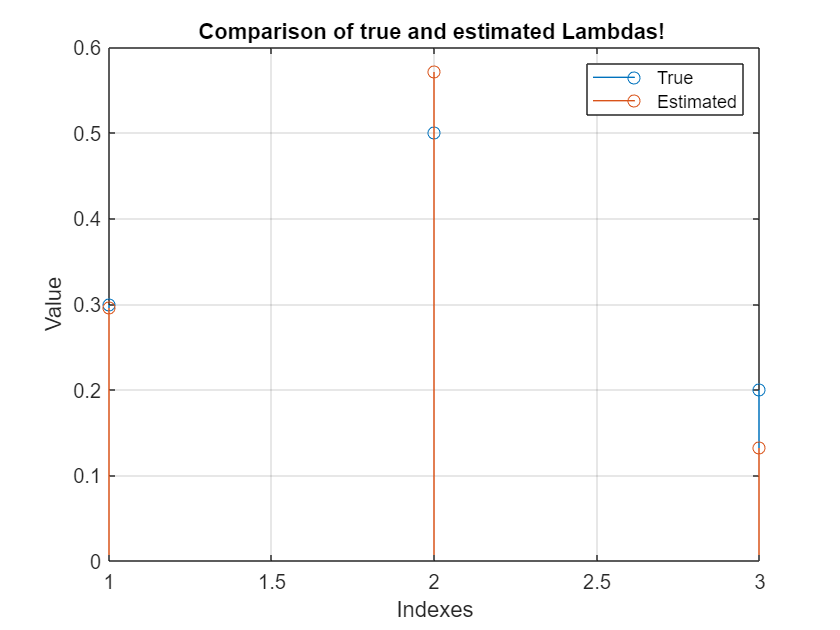

% To compare with true values we can:
% given true Lambdas we have: 
Lamb_True = [0.3; 0.5; 0.2];
figure()
stem(Lamb_True)
hold on
stem(Lambdas)
grid on
title('Comparison of true and estimated Lambdas! ')
ylabel('Value')
xlabel('Indexes')
legend('True','Estimated')

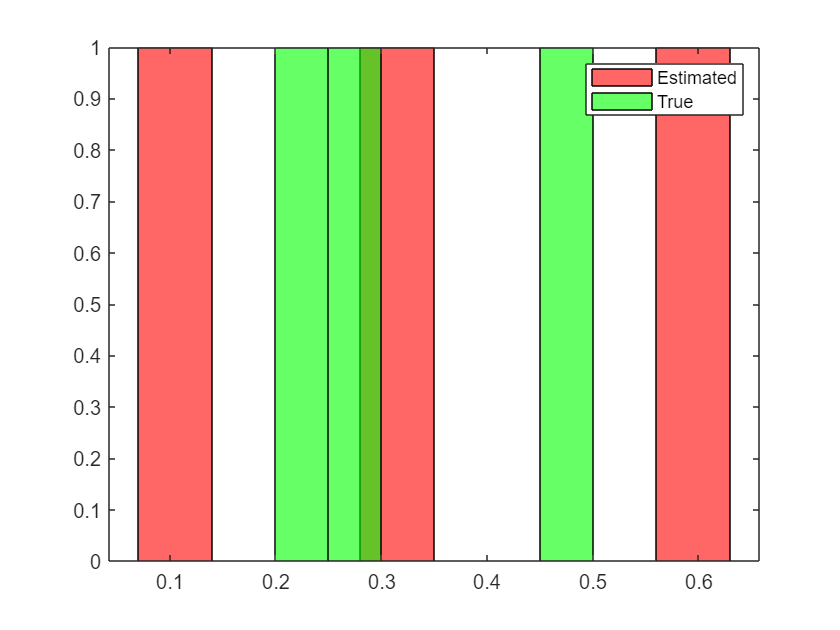

figure()
histogram(Lambdas','FaceColor','red','BinWidth',0.07);
hold on
histogram(Lamb_True','FaceColor','g','BinWidth',0.05);
legend('Estimated','True')

% given 100 samples, we almost converged to true, given coefficients! -->
% more samples will probably produce much accurate results!
% Anyway, we were able to estimate PDF, using given samples!

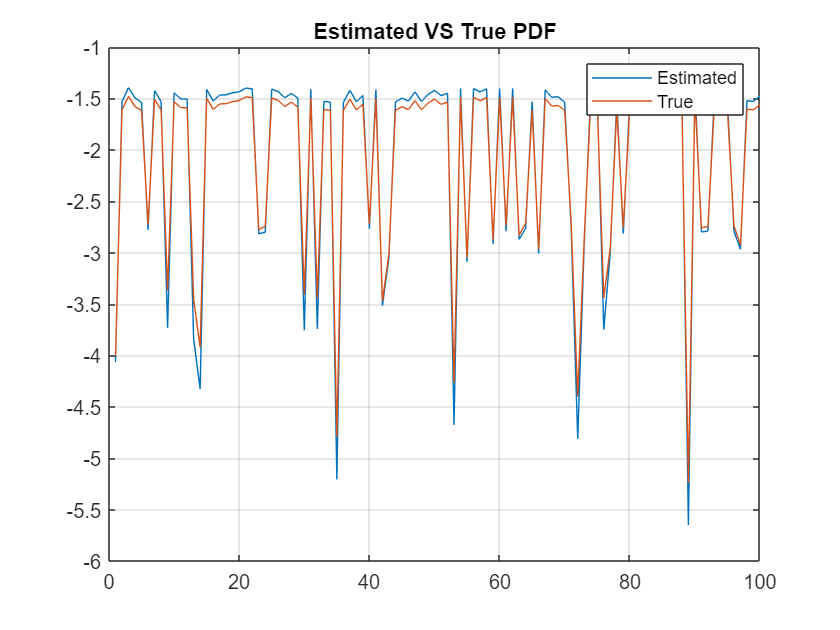

figure()
plot(log(p*Lambdas))
hold on
plot(log(p*Lamb_True))
grid on
title('Estimated VS True PDF')
legend('Estimated','True')